clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

% Load directory with the raw files
load('data/processed/sample4_20230512_mwpw.mat');

# Fit

Not enough resolution to fit the spin systems. Multifrequency will help in this regard.

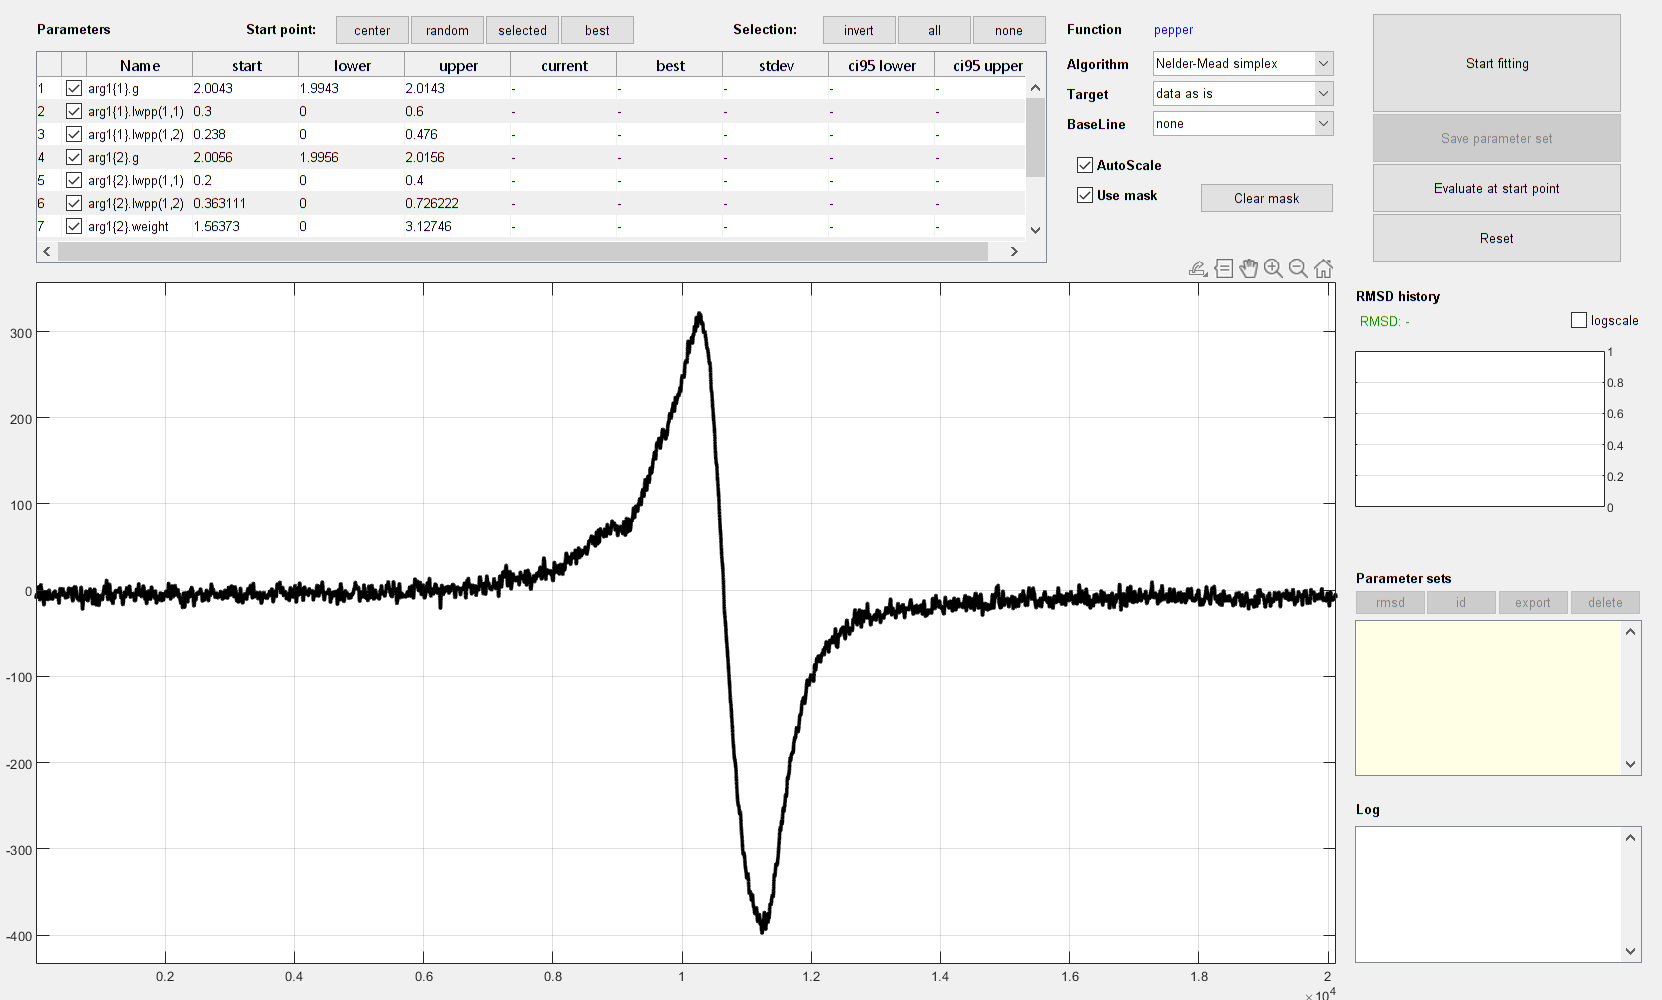

ICW = 4;
Sys1 = struct('g', 2.0043, ...
    'lwpp', [0.3 0.238]);
Sys2 = struct('g', 2.0056, ...
    'lwpp', [0.2 0.363111], ...
    'weight', 1.56373);
Sys3 = struct('g', 2.007, ...
    'lwpp', [0.2 0.50664], ...
    'weight', 1.5191);
Sys4 = struct('g', 2.01, ...
    'lwpp', [0.2 .08], ...
    'weight', 0.04);

Vary1 = struct('g', .01, ...
    'lwpp', Sys1.lwpp);
Vary2 = struct('g', .01, ...
    'lwpp', Sys2.lwpp, ...
    'weight', Sys2.weight);
Vary3 = struct('g', .01, ...
    'lwpp', Sys3.lwpp, ...
    'weight', Sys3.weight);
Vary4 = struct('g', .01, ...
    'lwpp', Sys4.lwpp, ...
    'weight', Sys4.weight);

Exp.Range = [min(cw(ICW).x) max(cw(ICW).x)];
Exp.mwFreq = cw(ICW).Params.MwFreq;
Exp.nPoints = numel(cw(ICW).x);

FitOpt.maxTime = 10;
FitOpt.PrintLevel = 0;

% Fit = esfit(yy, @pepper, {{Sys1, Sys2, Sys3}, Exp}, {{Vary1, Vary2, Vary3}}, FitOpt)
esfit(cw(ICW).y, @pepper, {{Sys1, Sys2, Sys4}, Exp}, {{Vary1, Vary2, Vary4}})

% Fit = esfit(yy, @pepper, {Sys1, Exp}, {Vary1}, FitOpt);

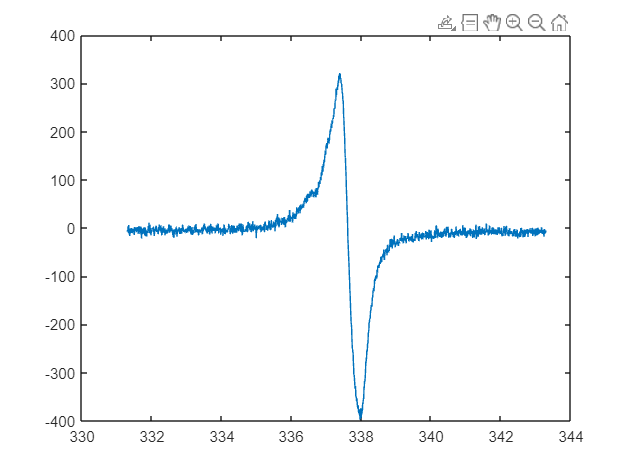

Sys1f = struct('g', 2.0043, ...
    'lwpp', [0.3068 0.2281]);
Sys2f = struct('g', 2.0058, ...
    'lwpp', [0.1677 0.3492], ...
    'weight', 1.7510);
Sys4f = struct('g', 2.0077, ...
    'lwpp', [0.2251 0.8298], ...
    'weight', 2.0587);

figure()
plot(cw(ICW).x, cw(ICW).y)
hold on

Opt.Output = 'separate';
plot(cw(ICW).x, fit1.scale*pepper({Sys1f, Sys2f, Sys4f}, Exp, Opt))

Unable to resolve the name 'fit1.scale'.